        Opgave 1



% opgave 1.3 


% denne kode er devist elle fuldstændigt givet sol løsning til E23 Exam i
% løsningsforslaget!! 
W = -pi:0.001:pi;
mag = 10-2*cos(2*W)-8*cos(W)

mag =    16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000


phase = -2*W % denne er den fase som er i arg(H(w)) = exp(-2Iw) i dette tilfælde, man fjerner dog I 

phase =     6.2832    6.2812    6.2792    6.2772    6.2752    6.2732    6.2712    6.2692    6.2672    6.2652    6.2632    6.2612    6.2592    6.2572    6.2552    6.2532    6.2512    6.2492    6.2472    6.2452    6.2432    6.2412    6.2392    6.2372    6.2352    6.2332    6.2312    6.2292    6.2272    6.2252    6.2232    6.2212    6.2192    6.2172    6.2152    6.2132    6.2112    6.2092    6.2072    6.2052    6.2032    6.2012    6.1992    6.1972    6.1952    6.1932    6.1912    6.1892    6.1872    6.1852


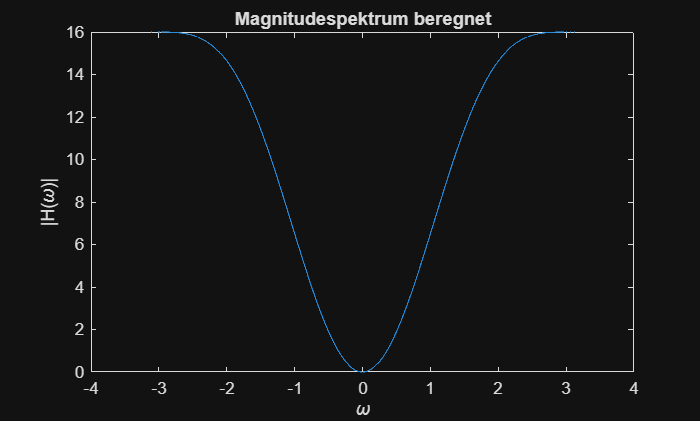

f1 = figure;
plot(W, mag);
title('Magnitudespektrum beregnet')
xlabel('\omega')
ylabel('|H({\omega})|')

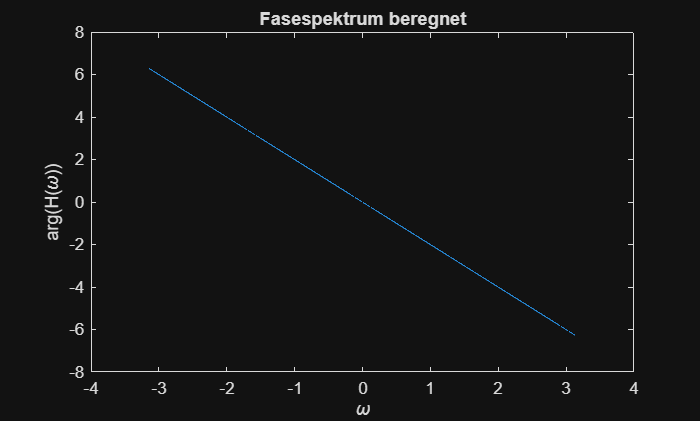

f2 = figure;
plot(W, phase);
title('Fasespektrum beregnet')
xlabel('\omega')
ylabel('arg(H({\omega}))') 

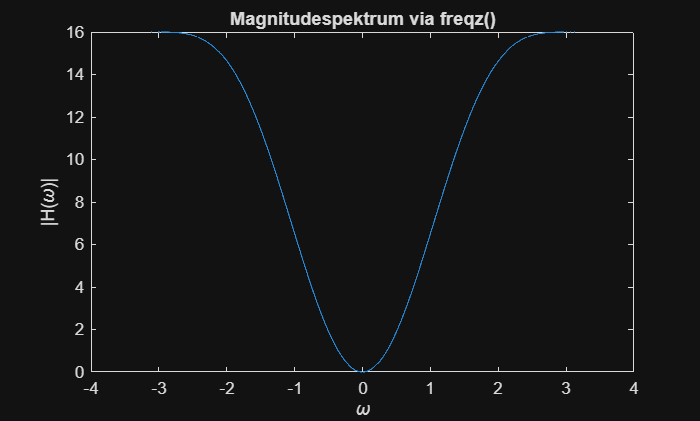


% Definer A,B koefficenter og omega-interval
A = [1];
B = [-1 -4 10 -4 -1];
H_d = freqz(B,A,W);
mag_d = abs(H_d);
phase_d = angle(H_d);
f3 = figure;
plot(W,mag_d);
title('Magnitudespektrum via freqz()')
xlabel('\omega')
ylabel('|H({\omega})|')

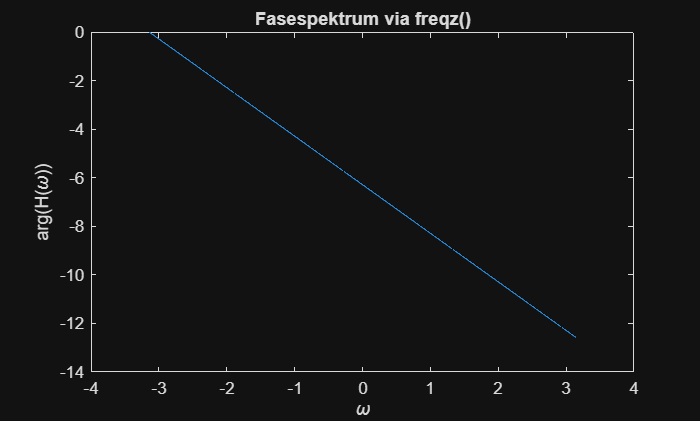

f4 = figure;
plot(W,unwrap(phase_d));
title('Fasespektrum via freqz()')
xlabel('\omega')
ylabel('arg(H({\omega}))')

denne fil er til besvarelse af E23 Eksamen

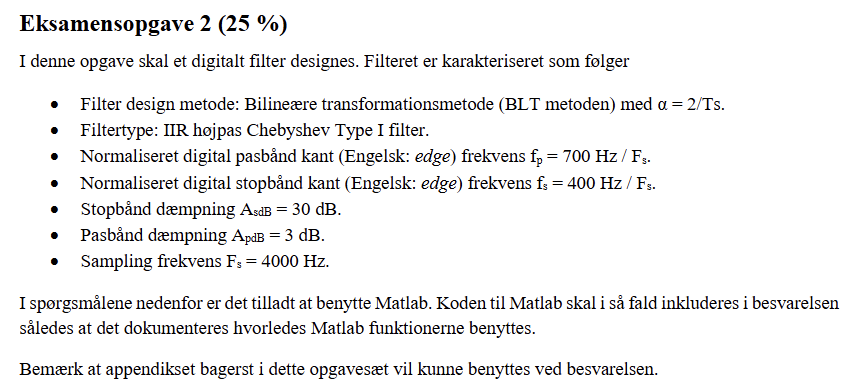

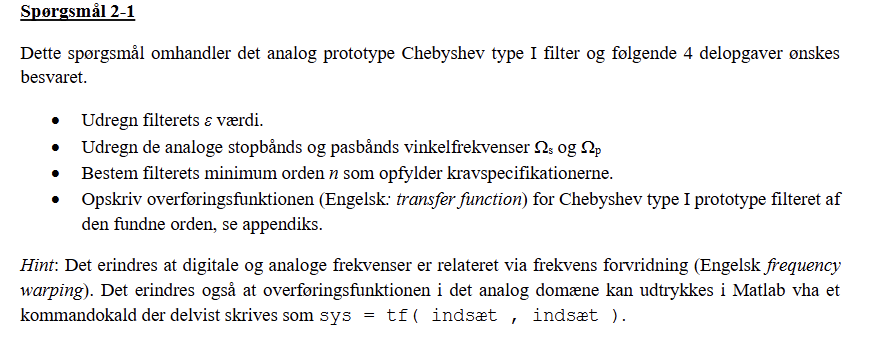

    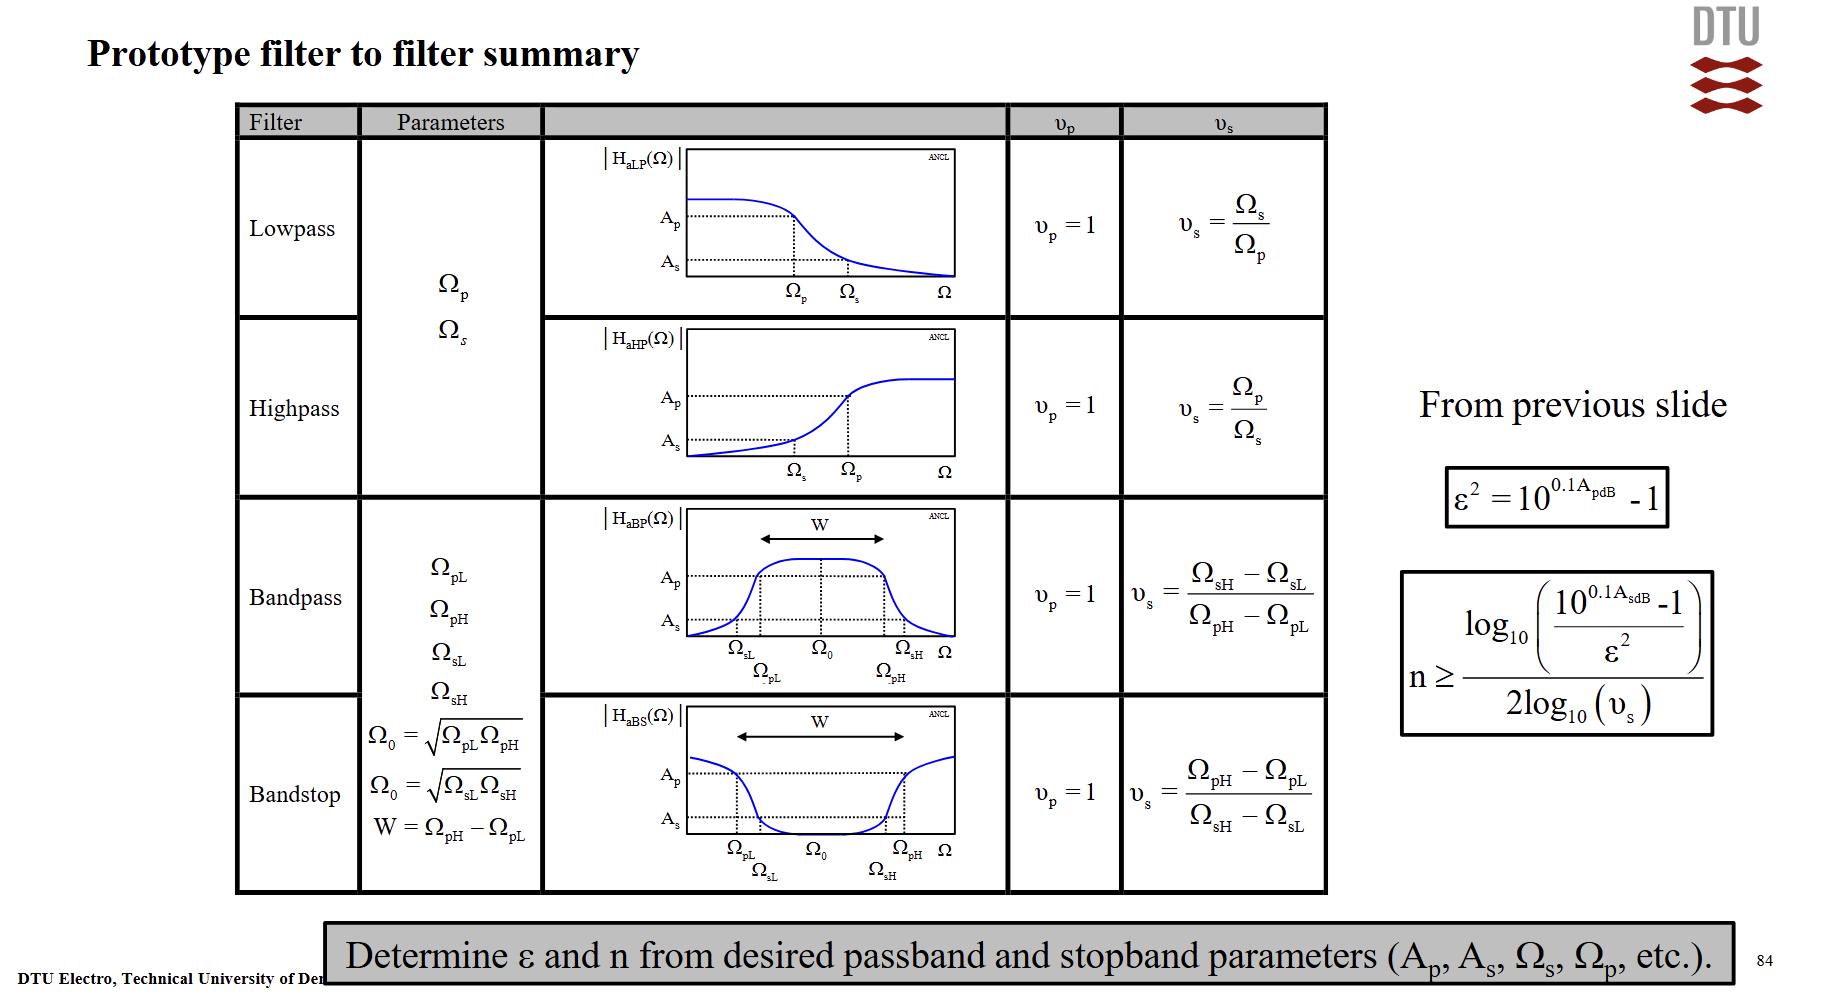

%IIR Højpass Chebyshev Type 1 Filter med bilinear metoden 

Fs = 4000; 
Ts = 1/Fs; 
AsdB = 30; 
ApdB = 3; 
fpb = 700/Fs; 
fsb = 400/Fs; 

alpha = 2/Ts;

%vi finder epsilon
epsilon_i_anden = (10^(0.1*ApdB))-1

epsilon_i_anden = 0.9953

epsilon = sqrt(epsilon_i_anden)

epsilon = 0.9976


%for at kunne finde de angulære frekvenser skal vi først finde de
%normaliserede angulære digitale frekvenser

wpb = fpb*2*pi

wpb = 1.0996

wsb =fsb*2*pi

wsb = 0.6283


%vi får 
% wpb = 1.0996---------------resultat --------------------
% wsb = 0.6283---------------resultat --------------------

%analoge normaliserede angulære frekvenser 
Opb = (2/Ts)*tan(wpb/2)

Opb = 4.9024e+03

Osb = (2/Ts)*tan(wsb/2)

Osb = 2.5994e+03


%vi får:
%Opb = 4902.4 rads---------------resultat --------------------
%Osb = 2599.4 rads ---------------resultat --------------------

% for at finde det laveste ordens filter vi kan bruge skal vi lave ntest
% derfor skal vi finde "new"


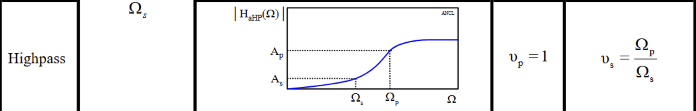

 news = Opb/Osb

news = 1.8860


%vi finder den minimale orden af et chebyshev Type 1 filter vi kan bruge 

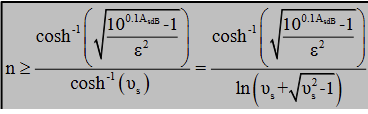

ntest = ( acosh( sqrt(  (10^(0.1*AsdB)-1)/(epsilon_i_anden) ) ) )/(acosh(news))

ntest = 3.3229

%ntest = 3.3229 -> 4. orden ---------------resultat --------------------

%vi får ntest = 3.3229 og skal derfor have n=4, det vil sige vi skal vælge det 4 ordens filter 

b = [0.1253]

b = 0.1253

a = [1 , 0.5816 , 1.1691 , 0.4048 , 0.1770]

a =     1.0000    0.5816    1.1691    0.4048    0.1770



H_ana_proto = tf(b,a)


H_ana_proto =
 
                      0.1253
  -----------------------------------------------
  s^4 + 0.5816 s^3 + 1.169 s^2 + 0.4048 s + 0.177
 
Continuous-time transfer function.




%                          0.1253
% H(s)=    -----------------------------------------------
%          s^4 + 0.5816 s^3 + 1.169 s^2 + 0.4048 s + 0.177

opgave 2.2

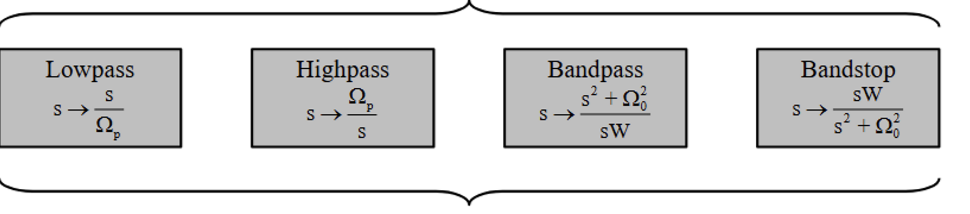

% vi kan her i matlab udregne highpass

%Vi skal i Hpass bruge (analoge) Omega pass da det er den frekvens vi
%transformerer til highpass med som man kan se på billedet ovenfor lp2xx
%kender transformationen så den skal bare fodres med den frekvens der er i
%transformationen
[num, den] = lp2hp(b,a,Opb)

num =     0.7079    0.0000    0.0000    0.0001    0.4291


den = 1.0e+15 *

    0.0000    0.0000    0.0000    0.0004    3.2634


% vi kan ikke se alle parametrene så vi udskriver dem så de ikke bare er 0

tf(num,den)


ans =
 
  0.7079 s^4 + 3.244e-12 s^3 + 3.577e-08 s^2 + 0.0001329 s + 0.4291
  -----------------------------------------------------------------
      s^4 + 1.121e04 s^3 + 1.587e08 s^2 + 3.871e11 s + 3.263e15
 
Continuous-time transfer function.


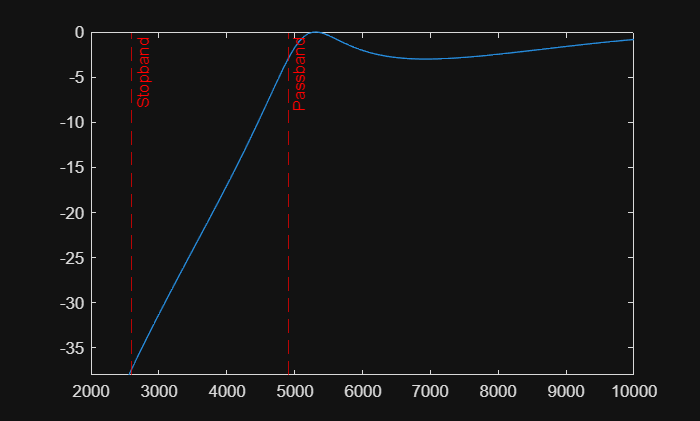



% vores højpass ser således ud 

%           0.7079 s^4 + 3.244e-12 s^3 + 3.577e-08 s^2 + 0.0001329 s + 0.4291
% H(s)=  ------------------------------------------------------------------
%              s^4 + 1.121e04 s^3 + 1.587e08 s^2 + 3.871e11 s + 3.263e15

[H_ana_H, anafreq] = freqs(num,den,1024);

plot(anafreq, 20*log10(abs(H_ana_H)))
xline(Osb,'--r', "Stopband") % indsætter en linje for stopbåndsfrek 
xline(Opb,'--r', "Passband") % indsætter en linje for passbåndsfrek 

xlim([2000,10000])
ylim([-38,0])

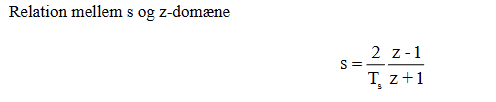

%opgave 2.3
%for at kunne udtrykke den digitale overføringsfunktion skal vi bruge denne
%komando nedenfor
[numdig,dendig] = bilinear(num,den,Fs)

numdig =     0.1100   -0.4401    0.6601   -0.4401    0.1100


dendig =     1.0000   -0.3269    0.9044    0.0742    0.3294



sys = tf(numdig,dendig,Ts,'Variable','z^-1')


sys =
 
  0.11 - 0.4401 z^-1 + 0.6601 z^-2 - 0.4401 z^-3 + 0.11 z^-4
  ----------------------------------------------------------
  1 - 0.3269 z^-1 + 0.9044 z^-2 + 0.07421 z^-3 + 0.3294 z^-4
 
Sample time: 0.00025 seconds
Discrete-time transfer function.


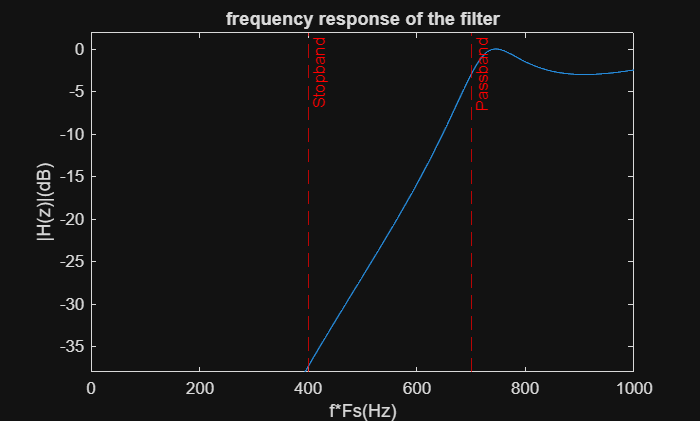


%resultatet 

%            0.11 - 0.4401 z^-1 + 0.6601 z^-2 - 0.4401 z^-3 + 0.11 z^-4
% H_HP=      ----------------------------------------------------------
%            1 - 0.3269 z^-1 + 0.9044 z^-2 + 0.07421 z^-3 + 0.3294 z^-4

[HHP_dig, freqdig] = freqz(numdig,dendig,1024,Fs);

plot(freqdig,20*log10(abs(HHP_dig)))
xline(fsb*Fs,'--r', "Stopband") % indsætter en linje for stopbåndsfrek 
xline(fpb*Fs,'--r', "Passband") % indsætter en linje for passbåndsfrek 

xlim([0,1000])
ylim([-38,2])

xlabel('f*Fs(Hz)')
ylabel(['|H(z)|(dB)'])
title('frequency response of the filter')
hold off

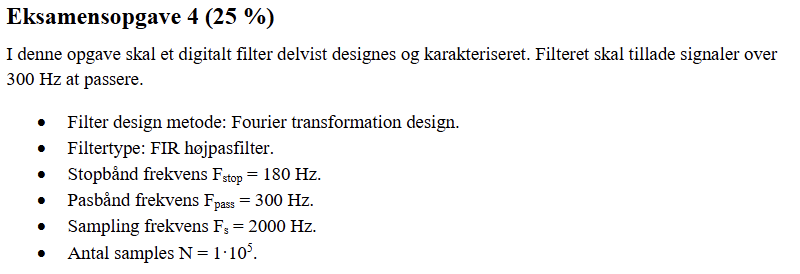

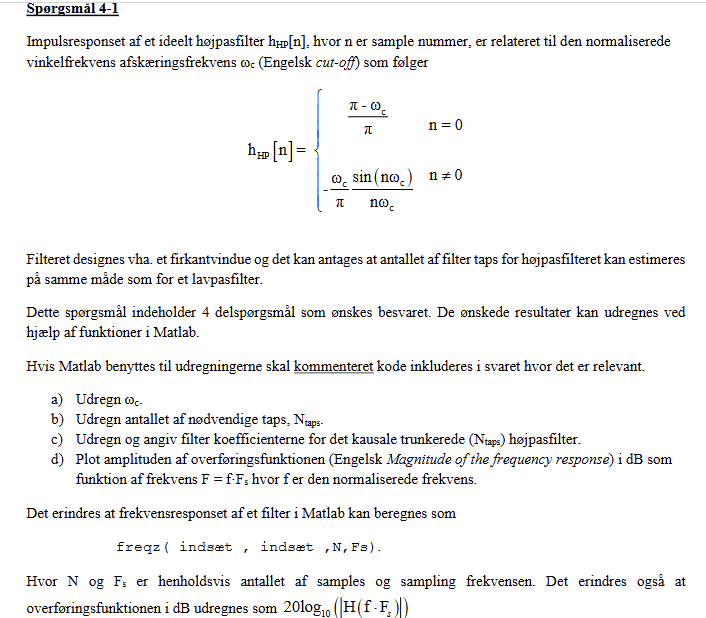

% opgivede variable

Fs = 2000; 
Fstop = 180; 
Fpass = 300; 
N = 1e5;


%a)  
%for at udregne wc følger vi metoden nedenfor

Fc = (Fstop+Fpass)/2

Fc = 240

fc = Fc/Fs

fc = 0.1200

wc = fc*2*pi

wc = 0.7540


%wc = 0.7540 --------resultat-------

%b)
%for at udregne antallet af Ntaps vi har brug for at finde sharpness først
%og herefter Ntaps

Sharp = abs(Fstop-Fpass)/Fs

Sharp = 0.0600

%Sharp = 0.2400

% vi kan nu finde antallet af Ntaps for et rektangulært vindue 

Ntaps = 0.9/Sharp

Ntaps = 15.0000


% Ntaps = 15 ---------resultat--------

%c)
M = Ntaps -1 

M = 14.0000

K = M/2

K = 7.0000

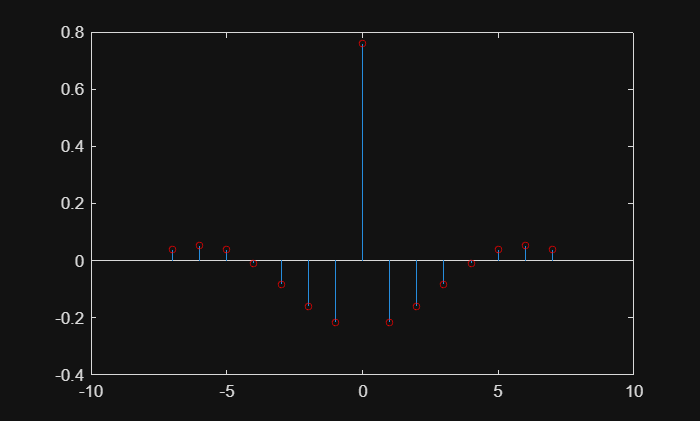

nHp = [-K:1:K];

hi_HP = -(wc/pi)*sinc((nHp*wc)/pi); % for n ikke lig    0 

% her er betingelserne på n == 0 opfyldt også 
h_ideel = hi_HP;               % gælder for alle n
h_ideel(nHp==0) = (pi - wc)/pi;     % KUN n = 0 rettes

% stem bare for at illustrere og hvi kan rigtigt nok se en trunkering 
stem(nHp,h_ideel,'lineWidth',0.4,'MarkerSize',4,'MarkerEdgeColor','red')
xlim([-10,10])
hold off

Hi_HP = tf(h_ideel,1,Ts);



h_ideel =     0.0384    0.0521    0.0374   -0.0100   -0.0818   -0.1588   -0.2179    0.7600   -0.2179   -0.1588   -0.0818   -0.0100    0.0374    0.0521    0.0384


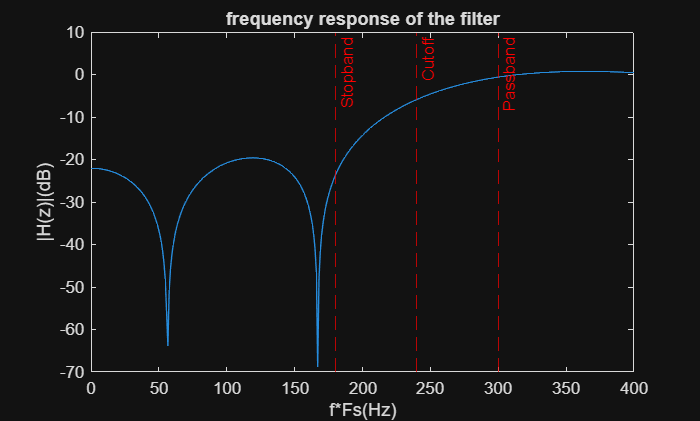


%filter koefficenterne er som følger: 
%b0= + 0.03839
%b1= + 0.05211
%b2= + 0.03742 
%b3= - 0.009974  
%b4= - 0.08175 
%b5= - 0.1588 
%b6= - 0.2179 
%b7= + 0.76 
%b8= - 0.2179  
%b9= - 0.1588 
%b10= - 0.08175 
%b11= - 0.009974  
%b12= + 0.03742 
%b13= + 0.05211
%b14= + 0.0383

% a0 = 1

[H,digfreq] = freqz(h_ideel,1,1024,Fs);


plot(digfreq,20*log10(abs(H)))
xlim([0,400])sds
xlabel('f*Fs(Hz)')
ylabel(['|H(z)|(dB)'])
title('frequency response of the filter')
xline(Fstop,'--r', "Stopband") % indsætter en linje for stopbåndsfrek 
xline(Fpass,'--r', "Passband") % indsætter en linje for passbåndsfrek 
xline(Fc,'--r', "Cutoff") % indsætter en linje for stopbåndsfrek 